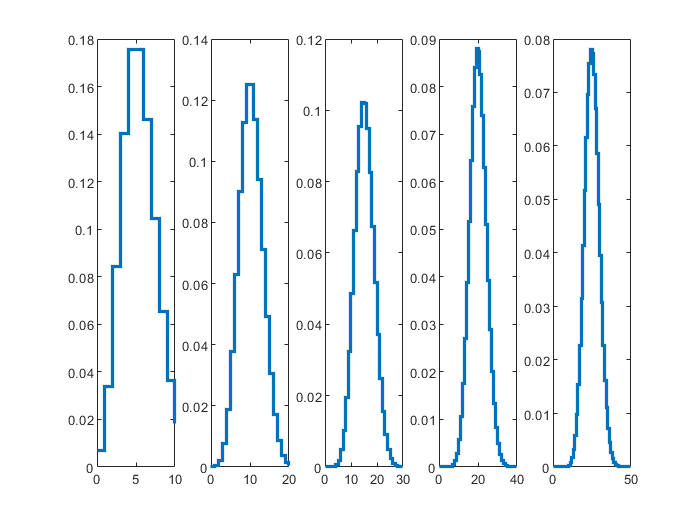

% Lab 2

cr = makedist('Poisson', 'lambda', 5); % Average cosmic-ray background
gr = makedist('Poisson', 'lambda', 7); % Average number of gamma-rays 

%1A

x = 0:10;
subplot(1, 5, 1)
stairs(x,pdf(cr,x),"LineWidth",2)
y = pdf(cr, x);
y1 = y;


for i = 1:4
    c = conv(y,y1);
    subplot(1,5,i+1)
    x = 0:10*(i+1);
    stairs(x,c,"LineWidth",2)
    y = c;
end


% The probability distribution becomes sharper since the majority of the
% data points are not at the peak. More fall along the base of the pdf, so
% the height of the pdf decreases also.

%1B
%As shown above, the peak becomes more refined as more samples are added to
%the base of the distribution. This narrows the peak profile and reduces
%the height.

%1C

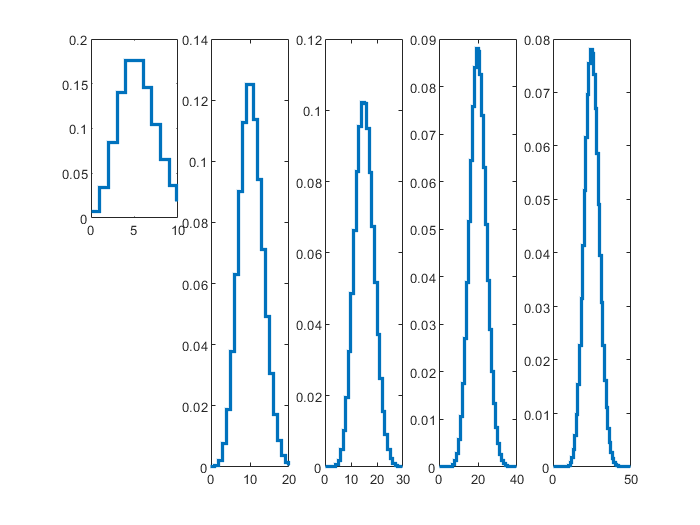


x = 0:10;
subplot(2, 5, 1)
stairs(x,pdf(cr,x),"LineWidth",2);

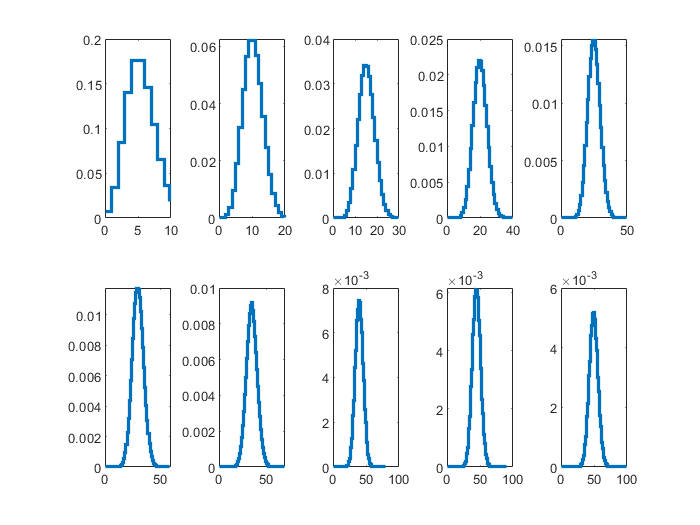

Error using subplot (line 332)
Index exceeds number of subplots.

y = pdf(cr, x);
y1 = y;

for i = 1:10
    c = conv(y,y1);
    subplot(2,5,i+1)
    x = 0:10*(i+1);
    stairs(x,c/(i+1),"LineWidth",2);
    y = c;
end


% As the days become larger, the height of the distribution is reduced and
% the base becomes wider. The curve becomes less discrete as the number of
% iterations increases. 
%1D